# Homework Assignment 1 : Rigid Transformation

## Objective : 

การบ้านนี้ถูกออกแบบึ้นมาเพื่อให้ผู้เรียนได้ประยุกต์ใช้องค์ความรู้เรื่องท่าทางของการเคลื่อนที่และการแปลงในปริภูมิ 3 มิติ

## Summary : 

ท่าทาง (Pose) คือลักษณะของวัตถุในปริภูมิ 3 มิติซึ่งประกอบไปด้วยทิศทางหมุน (Orientation) และ ตำแหน่ง (Position) เราสามารถระบุตำแหน่งของจุด $A$ ที่สัมพัทธ์กับจุดกำเนิดของพิกัดเฟรม $F_G$ และอ้างอิงกับพิกัดเฟรม $F_G$โดยใช้เวกเตอร์(หลัก) 3 มิติ 


$${\mathbf{p}}_{G,A}^G ={\left\lbrack \begin{array}{ccc}
p_x  & p_y  & p_z 
\end{array}\right\rbrack }^{\top }$$


แต่ทิศทางหมุนสามารถระบุได้หลากหลายรูปแบบ เช่น ZYZ-Euler angles 


$${\mathbf{r}}_{\textrm{ZYZ}}^G ={\left\lbrack \begin{array}{ccc}
\phi  & \theta  & \psi 
\end{array}\right\rbrack }^{\top }$$


หรือ Roll-Pitch-Yaw angles


$${\mathbf{r}}_{\textrm{RPY}}^G ={\left\lbrack \begin{array}{ccc}
r_x  & r_y  & r_z 
\end{array}\right\rbrack }^{\top }$$


นอกจากนี้ทิศทางหมุนยังสามารถเขียนในรูปของเมตริกซ์ตั้งฉากพิเศษ (Special Orthogonal Matrix ${\textrm{SO}}_3$) หรือเมตริกซ์การหมุนได้อีกด้วย  (Rotation Matrix)


$${\mathbf{R}}_A^G =\left\lbrack \begin{array}{ccc}
{\hat{\mathbf{x}} }_A^G  & {\hat{\mathbf{y}} }_A^G  & {\hat{\mathbf{z}} }_A^G 
\end{array}\right\rbrack$$


ดังนั้น เราไม่สามารถใช้เมตริกซ์ 3คูณ3ใดๆได้เลย เมตริกซ์การหมุนนั้นจำเป็นต้องมีคุณสมบัติดังต่อไปนี้


$$\begin{array}{l}
{\mathbf{R}}_A^G {{\mathbf{R}}_A^G }^{\top } ={\mathbf{I}}_3 \\
\det \left({\mathbf{R}}_A^G \right)=1
\end{array}$$


นอกจากการอธิบายท่าทางของวัตถุในปริภูมิ 3 มิติแล้ว เรายังสามารถใช้หลักการคำนวณเดียวกันในการแปลง (transform) วัตถุได้อีกด้วย ใช่ว่าการแปลงนั้นจะสามารถใช้ได้กับวัตถุทุกชนิด เราจำเป็นที่จะต้องคำนึงถึงประเภทของวัตถุนั้นอีกด้วย 

disp(table({'ทิศทางหมุน','ตำแหน่ง','ท่าทาง'}',{'หมุน','หมุน, เลื่อน','หมุน, เลื่อน'}','VariableNames',{'ประเภทวัตถุ','การแปลง'}))

     ประเภทวัตถุ          การแปลง     
    ______________    ________________

    {'ทิศทางหมุน'}    {'หมุน'        }
    {'ตำแหน่ง'   }    {'หมุน, เลื่อน'}
    {'ท่าทาง'    }    {'หมุน, เลื่อน'}



หากเรามีทิศทางหมุน ${\mathbf{R}}_B^G$ และทำการหมุนรอบแกน"ตรึง"ด้วยการหมุน $\mathbf{R}$เราจะได้ทิศทางหมุนอันใหม่เป็นดังต่อไปนี้


$${\mathbf{R}}^{\prime } =\mathbf{R}{\mathbf{R}}_B^G$$


หากเรามีตำแหน่ง ${\mathbf{p}}_{G,B}^G$ และทำการหมุนรอบแกน"ปัจจุบัน"ด้วยการหมุน $\mathbf{R}$แล้วทำการเลื่อนด้วยระยะ $\mathbf{p}$ เราจะได้ตำแหน่งใหม่เป็นดังต่อไปนี้


$${\mathbf{p}}^{\prime } =\mathbf{R}{\mathbf{p}}_{G,B}^G +\mathbf{p}$$


เราสามารถเขียนสมการเบื้องต้นในรูปของเมตริกซ์การแปลงแบบเอกพันธุ์ (Homogenous Transformation Matrix) ได้ดังต่อไปนี้


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
{\mathbf{p}}^{\prime } \\
\cdots \\
1
\end{array}\right\rbrack =\mathbf{H}\left\lbrack \begin{array}{c}
{\mathbf{p}}_{G,B}^G \\
\cdots \\
1
\end{array}\right\rbrack \\
\mathbf{H}=\left\lbrack \begin{array}{ccc}
\mathbf{R} & \vdots  & \mathbf{p}\\
\cdots  & \cdot  & \cdots \\
\left\lbrack \begin{array}{ccc}
0 & 0 & 0
\end{array}\right\rbrack  & \vdots  & 1
\end{array}\right\rbrack 
\end{array}$$


หากเรามีท่าทางทั้งทิศทางหมุน ${\mathbf{R}}_B^G$ และตำแหน่ง ${\mathbf{p}}_{G,B}^G$ และทำการหมุนรอบแกน"ปัจจุบัน"ด้วยการหมุน $\mathbf{R}$แล้วทำการเลื่อนด้วยระยะ $\mathbf{p}$ เราจะได้ท่าทางใหม่เป็นดังต่อไปนี้


$$\left\lbrack \begin{array}{ccc}
{\mathbf{R}}^{\prime }  & \vdots  & {\mathbf{p}}^{\prime } \\
\cdots  & \cdot  & \cdots \\
\left\lbrack \begin{array}{ccc}
0 & 0 & 0
\end{array}\right\rbrack  & \vdots  & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\mathbf{R} & \vdots  & \mathbf{p}\\
\cdots  & \cdot  & \cdots \\
\left\lbrack \begin{array}{ccc}
0 & 0 & 0
\end{array}\right\rbrack  & \vdots  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
{\mathbf{R}}_B^G  & \vdots  & {\mathbf{p}}_{G,B}^G \\
\cdots  & \cdot  & \cdots \\
\left\lbrack \begin{array}{ccc}
0 & 0 & 0
\end{array}\right\rbrack  & \vdots  & 1
\end{array}\right\rbrack$$


หรือ


$${\mathbf{H}}^{\prime } =\mathbf{H}{\mathbf{H}}_B^G$$


## โจทย์ : 

คุณกับทีมมีหน้าที่จำลองการเคลื่อนที่ของหุ่นยนต์ผึ้งที่เคลื่อนที่ในปริภูมิ 2 มิติ 

### ข้อมูลเกี่ยวกับสนาม

หุ่นยนต์ผึ้งนี้จะเคลื่อนที่ในตารางที่แบ่งเป็นช่องหกเหลี่ยมด้านเท่า(ด้านแต่ละด้านมีความยาวเป็น 1 [m]) ซึ่งพื้นที่ที่หุ่นยนต์เคลื่อนที่นั้นสามารถระบุเป็นเลขพิกัดได้ดังต่อไปนี้

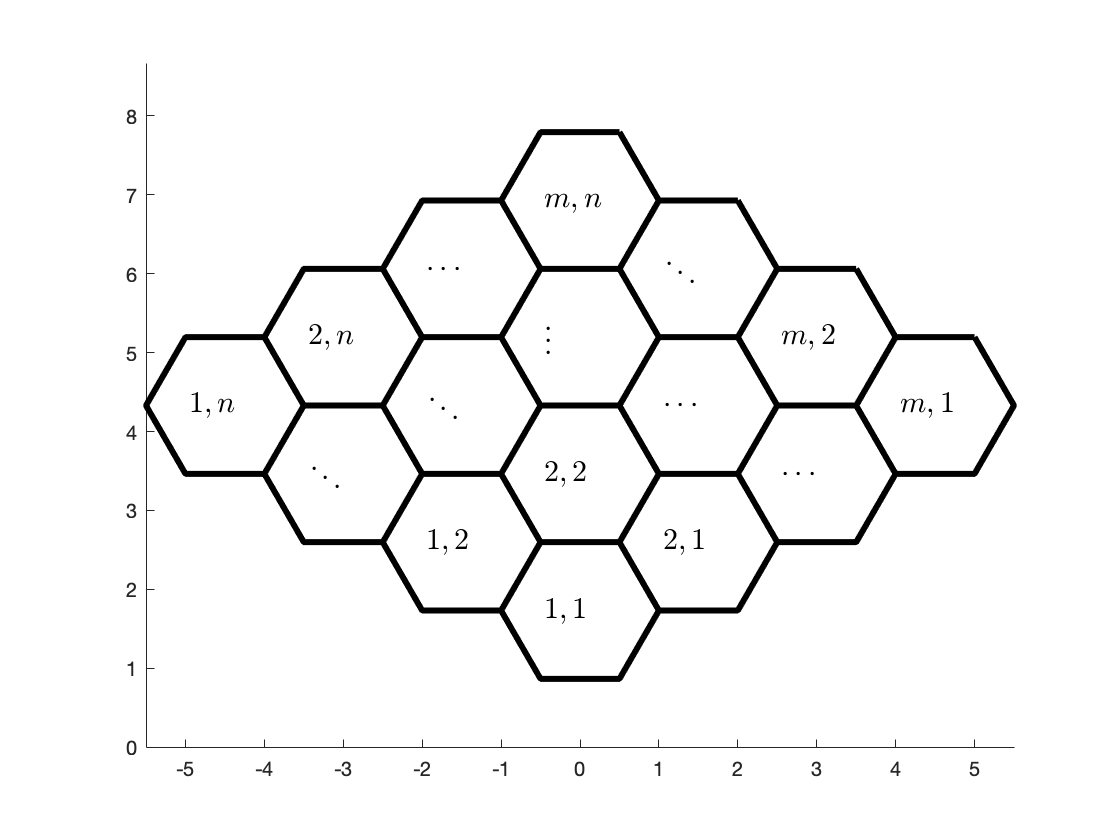

d = 1;
clf;
ax = axes;
hold(ax,'on');
axis(ax,'equal')
hex = d/(2*sin(pi/6))*[cos(2*pi*[1:6 1]/6);sin(2*pi*[1:6 1]/6)];
label = {'$1,1$','$1,2$','$\ddots$','$1,n$';'$2,1$','$2,2$','$\ddots$','$2,n$';'$\cdots$','$\cdots$','$\vdots$','$\cdots$';'$m,1$','$m,2$','$\ddots$','$m,n$'};
for i = 1:4
    hex_i = hex + [1.5;sqrt(3)/2]*d*(i-1);
    for j = 1:4
        hex_ij = hex_i + [-1.5;sqrt(3)/2]*d*(j-1)+[0;sqrt(3)];
        plot(ax,hex_ij(1,:),hex_ij(2,:),'k','linewidth',3)
        p = [1.5;sqrt(3)/2]*d*(i-1)+[-1.5;sqrt(3)/2]*d*(j-1)+[0;sqrt(3)];
        text(p(1)-0.45,p(2),label{i,j},'Interpreter','latex','FontSize',15)
    end
end

พิกัดของช่องสามารถอธิบายได้โดยรหัสคู่$\;\mathbf{a}\;$ที่เป็นจำนวนเต็ม (บวก ลบ หรือ ศูนย์)


$$\mathbf{a}={\left\lbrack \begin{array}{cc}
a_r  & a_c 
\end{array}\right\rbrack }^{\top } \in {\mathbf{Z}}^2$$


หรือ ตำแหน่งของจุดกึ่งกลาง $\mathbf{p}$ ของช่องนั้นๆ


$$\mathbf{p}={\left\lbrack \begin{array}{cc}
p_x  & p_y 
\end{array}\right\rbrack }^{\top } \in \Re^2$$


เรากำหนดให้ช่อง ${\mathbf{a}}_{0,0} ={\left\lbrack \begin{array}{cc}
0 & 0
\end{array}\right\rbrack }^{\top }$ มีตำแหน่งอยู่ที่ ${\mathbf{p}}_{0,0} ={\left\lbrack \begin{array}{cc}
0 & 0
\end{array}\right\rbrack }^{\top } \left\lbrack \mathrm{m}\right\rbrack$

### ข้อมูลเกี่ยวกับสิ่งกีดขวาง

สนามสามารถมีสิ่งกีดขวางได้ซึ่งสิ่งกีดขวางนั้นจะกินพื้นที่ทั้งช่องหกเหลี่ยม เราสามารถระบุได้ว่าทั้งสนามนั้นมีช่องที่เป็นสิ่งกีดขวางทั้งหมดกี่ช่องโดยเขียนในรูปของ array ของรหัสช่อง $\mathbf{O}\in {\mathbf{Z}}^{2\times n} \;$โดยที่ $n$ เป็นจำนวนของช่องที่เป็นสิ่งกีดขวาง ยกตัวอย่างเช่น


$$\mathbf{O}=\left\lbrack \begin{array}{cccc}
{\mathbf{a}}_{-1,1}  & {\mathbf{a}}_{1,1}  & {\mathbf{a}}_{0,-1}  & {\mathbf{a}}_{2,-1} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
-1 & 1 & 0 & 2\\
1 & 1 & -1 & -1
\end{array}\right\rbrack$$


O = [-1 1 0 2;1 1 -1 -1];
min_i = min(O(1,:));
max_i = max(O(1,:));
min_j = min(O(2,:));
max_j = max(O(2,:));

d = 1;
clf;
ax = axes;
hold(ax,'on');
axis(ax,'equal')
hex = d/(2*sin(pi/6))*[cos(2*pi*[1:6 1]/6);sin(2*pi*[1:6 1]/6)];

hex =     0.5000   -0.5000   -1.0000   -0.5000    0.5000    1.0000    0.5000
    0.8660    0.8660    0.0000   -0.8660   -0.8660   -0.0000    0.8660


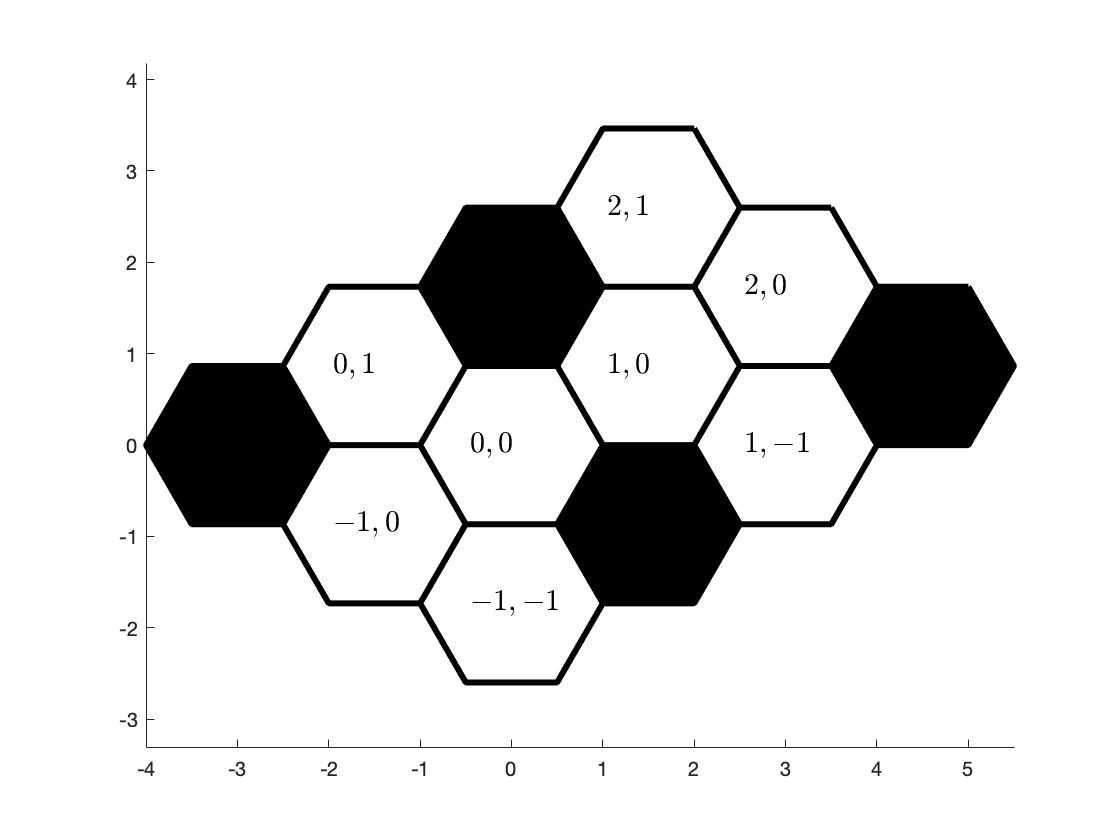

for i = min_i:max_i
    hex_i = hex + [1.5;sqrt(3)/2]*d*(i-1);
    for j = min_j:max_j
        hex_ij = hex_i + [-1.5;sqrt(3)/2]*d*(j-1)+[0;sqrt(3)];
        plot(ax,hex_ij(1,:),hex_ij(2,:),'k','linewidth',3)
        p = hex_ij-hex;
        label = ['$' num2str(i) ',' num2str(j) '$'];
        text(p(1)-0.45,p(2),label,'Interpreter','latex','FontSize',15)
    end
end
for k = 1:size(O,2)
    hex_ij = hex + [1.5;sqrt(3)/2]*d*(O(1,k)-1)+[-1.5;sqrt(3)/2]*d*(O(2,k)-1)+[0;sqrt(3)];
    patch(ax,hex_ij(1,:),hex_ij(2,:),[0,0,0])
end

### ข้อมูลเกี่ยวหุ่นยนต์

การทำงานของหุ่นยนต์มีลักษณะดังต่อไปนี้

- หุ่นยนต์เริ่มต้นที่จุดกึ่งกลางของช่อง ${\mathbf{a}}_{0,0}$ โดยที่เริ่มต้นหันหน้าไปที่ช่อง ${\mathbf{a}}_{1,1}$

- หุ่นยนต์สามารถรับคำสั่งได้ทั้งหมด 5 ปะรเภทซึ่งสามารถเข้ารหัสได้ดังต่อไปนี้

command = 0:4;
behavior = {'อยู่กับที่','เดินไปข้างหน้า 1 ช่อง','ถอยหลัง 1 ช่อง','หันซ้าย 60 องศา','หันขวา 60 องศา'};
table(command',behavior','VariableNames',{'คำสั่ง','พฤติกรรม'})

ans = 5×2 table
    คำสั่ง            พฤติกรรม         
    ______    _________________________

      0       {'อยู่กับที่'           }
      1       {'เดินไปข้างหน้า 1 ช่อง'}
      2       {'ถอยหลัง 1 ช่อง'       }
      3       {'หันซ้าย 60 องศา'      }
      4       {'หันขวา 60 องศา'       }


- หากหุ่นยนต์ได้รับคำสั่งให้เดินไปข้างหน้า 1 ช่องแต่ว่าในช่องนั้นมีสิ่งกีดขวางอยู่ หุ่นยนต์จะอยู่ที่ช่องเดิม

- หากหุ่นยนต์ได้รับคำสั่งให้ถอยหลัง 1 ช่องแต่ว่าในช่องนั้นมีสิ่งกีดขวางอยู่ หุ่นยนต์จะอยู่ที่ช่องเดิม

 จงเขียนโปรแกรม trackBeeBot ในการหาเส้นทาง(ลำดับของช่องทั้งหมดที่หุ่นยนต์เดินผ่าน)ในรูปแบบของรหัส $\mathbf{A}$ และตำแหน่ง $\mathbf{P}$ โดยกำหนดรหัสของช่องเริ่มต้น ${\mathbf{a}}_i$ ลำดับของคำสั่ง $\mathbf{c}$  และสิ่งกีดขวาง $\mathbf{W}$


$$\left\lbrack \mathbf{A},\mathbf{P}\right\rbrack =\textrm{trackBeeBot}\left({\mathbf{a}}_i ,\mathbf{c},\mathbf{W}\right)$$


-  $\mathbf{A}\in {\mathbf{Z}}^{2\times m}$ และ $\mathbf{P}\in \Re^{2\times m}$ โดยที่ $m$ เป็นจำนวนของช่องที่หุ่นยนต์วิ่งผ่านตามลำดับ(วิ่งผ่านช่องเดิมได้)


$$\begin{array}{l}
\mathbf{A}=\left\lbrack \begin{array}{cccccc}
{\mathbf{a}}_{\left\lbrack 1\right\rbrack }  & {\mathbf{a}}_{\left\lbrack 2\right\rbrack }  & \cdots  & {\mathbf{a}}_{\left\lbrack k\right\rbrack }  & \cdots  & {\mathbf{a}}_{\left\lbrack m\right\rbrack } 
\end{array}\right\rbrack \\
\mathbf{P}=\left\lbrack \begin{array}{cccccc}
{\mathbf{p}}_{\left\lbrack 1\right\rbrack }  & {\mathbf{p}}_{\left\lbrack 2\right\rbrack }  & \cdots  & {\mathbf{p}}_{\left\lbrack k\right\rbrack }  & \cdots  & {\mathbf{p}}_{\left\lbrack m\right\rbrack } 
\end{array}\right\rbrack \\
{\mathbf{a}}_{\left\lbrack k\right\rbrack } \not= {\mathbf{a}}_{\left\lbrack k-1\right\rbrack } \forall \;k=2,\cdots ,m\\
{\mathbf{p}}_{\left\lbrack k\right\rbrack } \not= {\mathbf{p}}_{\left\lbrack k-1\right\rbrack } \forall \;k=2,\cdots ,m\\
{\mathbf{a}}_{\left\lbrack 1\right\rbrack } ={\mathbf{a}}_i 
\end{array}$$


- $\mathbf{c}$ เป็น array ของ char ที่ประกอบไปด้วยเลข 0,1,2,3,และ 4 เท่านั้น

- $\mathbf{c}$ และ $\mathbf{W}$ สามารถเป็นเมตริกซ์เปล่าได้

* ไม่จำเป็นต้องจัดการ error case ในกรณีที่ใส่ขนาดผิด ใส่ตัวแปรผิดประเภท หรือใส่ช่องเริ่มในสิ่งกีดขวาง